# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5 ;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = true;                                                                  % Continue to next step when current step is done?
Deci.PCom               = true;                                                                  % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\Displaced'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-4 2];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Displace = 1;
Deci.DT.Block.Start   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {12};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                         % Scalar,High-bandpass filter, in Hz.
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []   ;
Deci.PP.Ocu = [];
Deci.PP.eog = {'TVEOG','BVEOG','LHEOG','RHEOG'};
Deci.PP.Manual = true;

## 3. Artifact Rejection

Deci.Art.crittoilim = [-1.5 .5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.PostICAbpf = [];                                                                       % Post ICA broadband pass filter, if desired

## 4. Analysis

#### Time-Frequency Analysis

Deci.Analysis.Freq.do            = true;
Deci_Wavelet;
Deci.Analysis.Freq.Toi           = [-1.5 .5];                                                  % Time Range to save
Deci.Analysis.Freq.Toilim        = [-3 2];

#### Cross-Frequency Coupling

% Specify channel to save time on specific CFC
%Deci.Analysis.Channels 
Deci.Analysis.CFC.do = true;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = ['Reinhart-All'];
Deci.Analysis.CFC.latencyhigh = [-1.5 .5]; %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-1.5 .5];

FreqBands = {'delta' 'theta' 'alpha' 'beta' 'lowgamma' 'highgamma'};
Deci.Analysis.CFC.freqhigh = FreqBands([ false true false false false false]);
Deci.Analysis.CFC.freqlow  = FreqBands([ false true false false false false]);
Deci.Analysis.CFC.timebin = 6;
Deci.Analysis.CFC.methods = {'mi' 'plv'};  % can only currently handle '' or 'mi'(pac)

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];

Extra

Deci.Analysis.Extra.QL.States = [20 21 23 24];
Deci.Analysis.Extra.QL.Actions = [31 32];
Deci.Analysis.Extra.QL.Reward  = [51 52];
Deci.Analysis.Extra.QL.Value  = {[20 10] [10 0] [0 -10] [-10 -20]};
%Deci.Analysis.Extra.QL.Start = @(c) [rand([1 2])*40]-20;
%Deci.Analysis.Extra.QL.Start = @(c) [0 0];

Deci.Analysis.Extra.RT.Lock = [1 2];

Deci.Analysis.Extra.Corr.Freq = {'Magnitude' 'Phase'};
Deci.Analysis.Extra.Corr.Variable = {'Q' 'Pe' 'RT'};
%Deci.Analysis.Extra.Corr.freqbin = {[1 4] [4 8] [8 12.5] [12.5 16] [16 20] [20 30] [30 55] [55 80]};
Deci.Analysis.Extra.Corr.freqbin = {[4 8] [8 12.5] [12.5 16] [16 20] [20 30] [30 40]};
Deci.Analysis.Extra.Corr.timebin = 6;

Deci.Analysis.Extra.Corr.Varnums = 2;
Deci.Analysis.Extra.Corr.Bsl     = [-.5 0];
Deci.Analysis.Extra.Corr.Downsample = [125];
Deci.Analysis.Extra.Corr.Regression = false;


Deci.Analysis.Extra.do = false;
Deci.Analysis.Extra.list = [true true true];
Deci.Analysis.Extra.Once = [ true true false];
Deci.Analysis.Extra.Functions = {'QL3' 'Deci_RT' 'Deci_Corr'};
Deci.Analysis.Extra.Params = {{Deci.Analysis.Extra.QL} {Deci.Analysis.Extra.RT} {Deci.Analysis.Extra.Corr}};

## 5. Plotting

Deci.Plot.Lock = 'Stim Onset';
Deci.Plot.BslRef = 'Stim Onset';
Deci.Plot.GrandAverage = true;
Deci.Plot.FreqYScale = 'linear';


#### Statistics

Deci.Plot.Stat.do = true;
Deci.Plot.Stat.Type = 'Anova/T-test';
Deci.Plot.Stat.alpha = .05;
Deci.Plot.Stat.correctm = 'no';
Deci.Plot.Stat.FPlots =  false;

#### Time-Frequency

Deci.Plot.Freq.Topo.do    =true;
Deci.Plot.Freq.Topo.Foi     = [4 8];                   % Frequency of Interest
Deci.Plot.Freq.Topo.Toi     = [0 .5];                   % Time of Interest
Deci.Plot.Freq.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.Freq.Square.do  =true;
Deci.Plot.Freq.Square.Foi     = [3 inf];                   % Frequency of Interest
Deci.Plot.Freq.Square.Toi     = [];                   % Time of Interest
Deci.Plot.Freq.Square.Channel = [{'Cz'}];                   % Channel of Interest

Deci.Plot.Freq.Wire.do    =true;
Deci.Plot.Freq.Wire.Foi     = [4 8];                   % Frequency of Interest
Deci.Plot.Freq.Wire.Toi     = [];                   % Time of Interest
Deci.Plot.Freq.Wire.Channel = [{'Cz'}];                   % Channel of Interest

Deci.Plot.Freq.Bar.do    =true;
Deci.Plot.Freq.Bar.Foi     = [4 8];                   % Frequency of Interest
Deci.Plot.Freq.Bar.Toi     = [0 .5];                   % Time of Interest
Deci.Plot.Freq.Bar.Channel = [{'Cz'}];                   % Channel of Interest

Deci.Plot.Freq.Type    = 'TotalPower';                   % Use 'TotalPower','ITPC' or 'EvokedPower' (Currently Unavailable)
Deci.Plot.Freq.Bsl     = [-.5 0];                             % Baseline Correction Time

**CFC**

%Currently Unavailable
Deci.Plot.CFC.methods = {'mi' 'plv'};
Deci.Plot.CFC.Topo = false;
Deci.Plot.CFC.Square = false;
Deci.Plot.CFC.Hist = false;
Deci.Plot.CFC.Wire = true;
Deci.Plot.CFC.Bsl = [-.2 0];

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = {'FCz'};
Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.ERP.Topo =true;
Deci.Plot.ERP.Wire =true;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Figure = [false true];
Deci.Plot.Behv.Acc.Total = {{[1:16] [1:16]} {[1 5 9 13] [2 6 10 14] [3 7 11 15] [4 8 12 16]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1:8] [9:16]} {[1 5] [2 6] [3 7] [4 8]}};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {{'Opt Percent' 'Wst Percent'} {'AB' 'CD' 'EF' 'GH'}};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;


Deci.Plot.Behv.RT.Figure = [false false];
Deci.Plot.Behv.RT.Draw = {{[1:8] [9:16]}  {[1 5] [2 6] [3 7] [4 8] [9 13] [10 14] [11 15] [12 16]} {}};
Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials RT'};
Deci.Plot.Behv.RT.Subtitle = {{'Opt' 'Worst'} {'Opt AB' 'Opt CD' 'Opt EF' 'Opt GH' 'Wst AB' 'Wst CD' 'Wst EF' 'Wst GH'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

** Extra**

Deci.Plot.Extra.List = true;
Deci.Plot.Extra.Functions = {'QL'};
Deci.Plot.Extra.Params = {{}};

## ** 6. Run**

#### General Set-Up

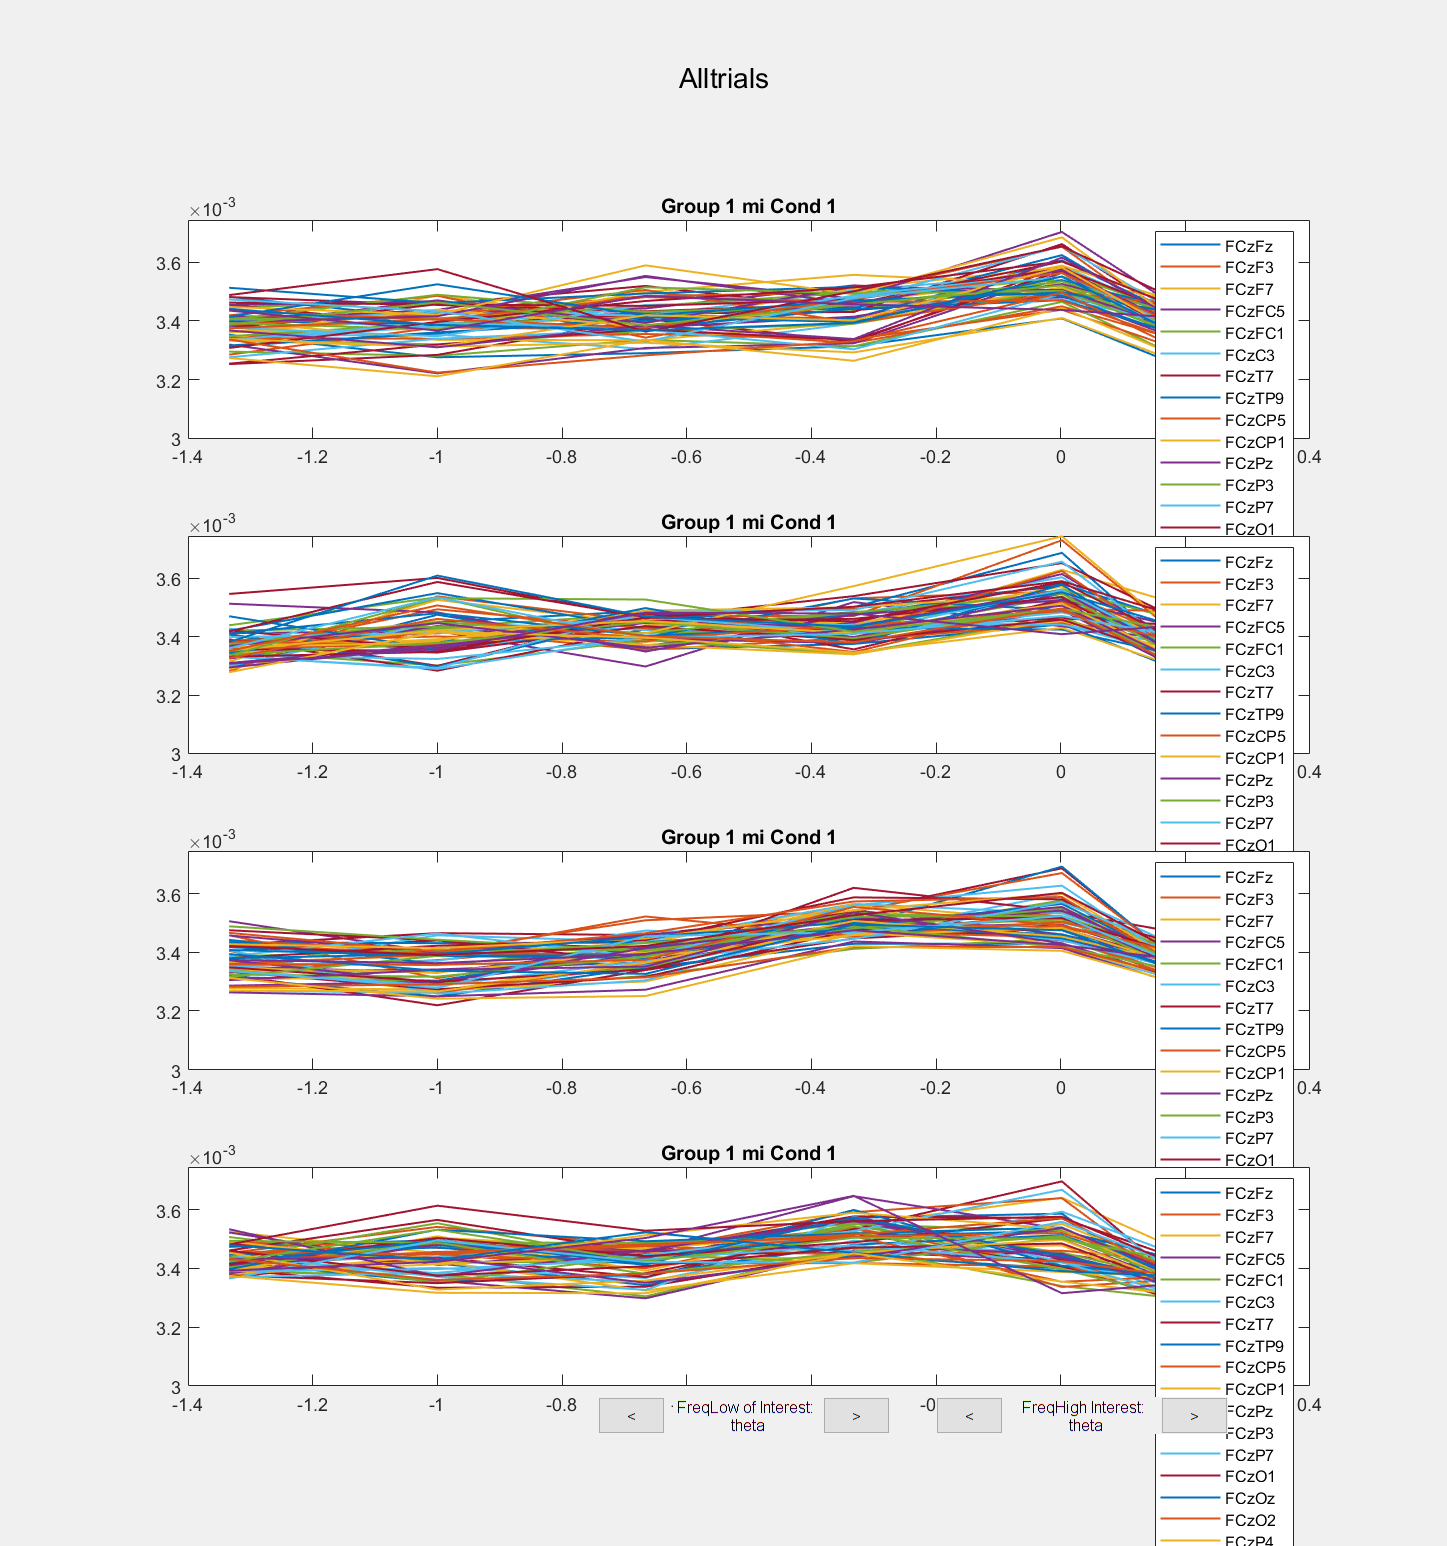

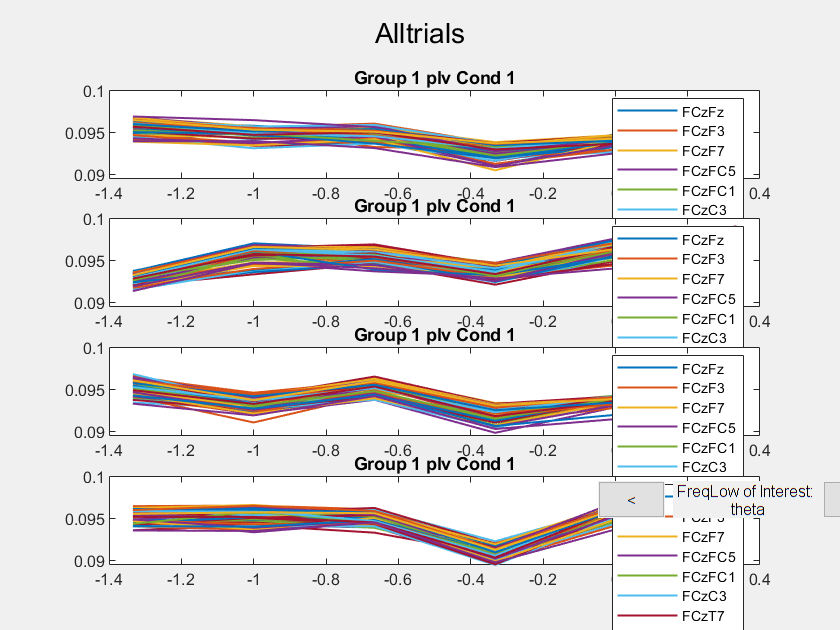

QLTrials;
Deci.Analysis.Version = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\Displaced'];

Deci.Plot.Version = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\Displaced'];
Deci.Analysis.Locks         = [1]; 
Deci.Analysis.LocksTitle    = {'Stim Onset'};   

Deci.Run.Behavior = false;
Deci.Run.Freq =false;
Deci.Run.ERP =false;
Deci.Run.CFC = true;
Deci.Run.Extra = false;

Deci_Backend(Deci);